clc
goal=@Fun;
A=[13,13.5,14,11.5;0.015,0.02,0.01,0.011];
b=[300*48;20];
aeq=[];
beq=[];
lb=[0 0 150 0];
ub=[270 240 460 130];
[x,fval]=gamultiobj(goal,4,A,b,aeq,beq,lb,ub);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =     0.0062    0.0068  150.0004    0.0198
  214.3347  224.2249  459.9481   85.7987
   33.8548  103.0412  165.0126   22.6036
   33.5519  130.4655  192.3752   50.7303
  123.9003   70.6178  194.0694    9.3496
  135.5733  141.3394  176.0012   36.5395
  185.3695  158.3413  408.0481   25.4638
   33.3630   15.5061  169.7514   11.8102
  181.3055  201.5505  454.4205   83.3918
  186.7699  145.1620  387.7434   53.6093


fval = 	1.0e+04 *

   -0.1800    0.0003
   -1.3348    0.0017
   -0.4696    0.0006
   -0.5964    0.0007
   -0.5111    0.0007
   -0.6806    0.0008
   -1.0274    0.0014
   -0.2846    0.0004
   -1.2465    0.0016
   -1.0174    0.0013


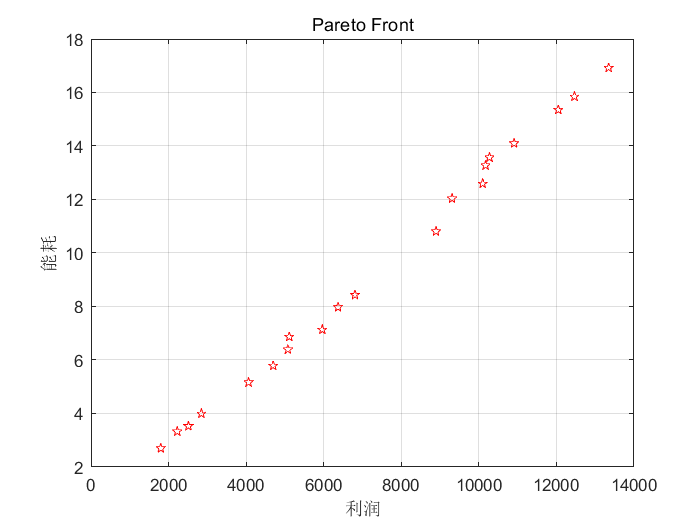

fval(:,1)=-fval(:,1);
[x,fval]
plot(fval(:,1),fval(:,2),'pr')
title('Pareto Front')
xlabel('利润')
ylabel('能耗')
grid on